clear 
H1 = tf(1000*[1, 6],[1, 20, 5000, 0])

H1 =
 
      1000 s + 6000
  ---------------------
  s^3 + 20 s^2 + 5000 s
 
Continuous-time transfer function.
Model Properties


H2 = tf(1000*[1, -6],[1, 20, 5000, 0])

H2 =
 
      1000 s - 6000
  ---------------------
  s^3 + 20 s^2 + 5000 s
 
Continuous-time transfer function.
Model Properties


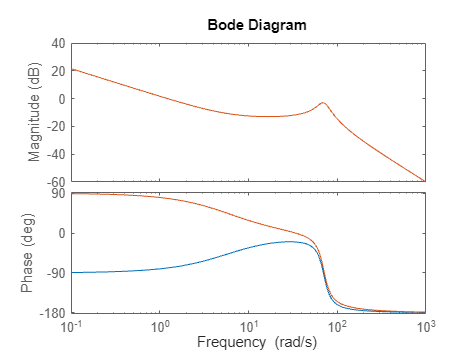


bode(H1,H2)


C = tf([1 1],[1])

C =
 
  s + 1
 
Continuous-time transfer function.
Model Properties


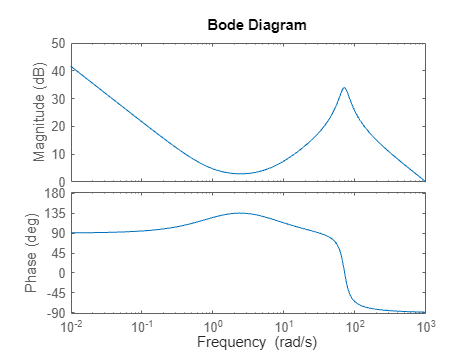

bode(H2*C)

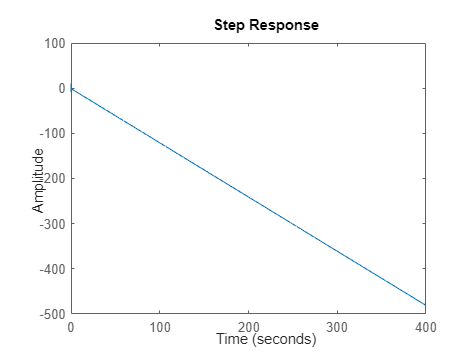

step(H2*C)